# Tutorial 

**2 Layer Neural Network**

clear all
clc

% Creating Training Set of Data

examp_1 = [0 1 1 0 ; 1 0 0 1 ; 1 0 0 1; 0 1 1 0];

examp_2 = [1 1 1 0 ; 1 0 1 0 ; 1 0 1 0; 1 1 1 0];

examp_3 = [0 1 1 1 ; 0 1 0 1 ; 0 1 0 1; 0 1 1 1];

examp_4 = [1 1 1 0 ; 1 0 0 1 ; 1 0 0 1; 1 1 1 0];

examp_5 = [0 1 0 0 ; 1 1 1 1 ; 0 1 0 0; 0 1 0 0];

examp_6 = [0 0 1 0 ; 1 1 1 1 ; 0 0 1 0; 0 0 1 0];

examp_7 = [1 1 1 1 ; 0 1 0 0 ; 0 1 0 0; 0 1 0 0];

examp_8 = [1 1 1 1 ; 0 0 1 0 ; 0 0 1 0; 0 0 1 0];

%[1 0] represents 0 digit
%[0 1] represents + digit

examp_labels = [1 0 ; 1 0 ; 1 0 ; 1 0 ; 0 1 ; 0 1 ; 0 1 ; 0 1 ];


%creating Test Data

test_1 = [1 1 1 1; 1 0 0 1; 1 0 0 1 ; 1 1 1 1];

test_2 = [1 1 1 1; 0 1 1 0; 0 1 1 0 ; 0 1 1 0];

test_3 = [1 1 1 1; 0 0 0 0; 0 0 0 0 ; 0 1 1 0];


%Flattening the inputs

examp_all = [examp_1(:), examp_2(:), examp_3(:), examp_4(:), ...
    examp_5(:), examp_6(:), examp_7(:), examp_8(:)];
examp_labels = examp_labels';


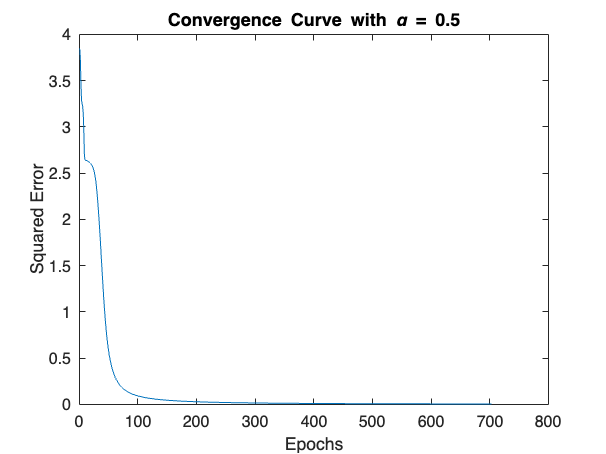

%Hidden Layers and initializations

%creating hidden layer and initalizing randomized weights
W_21 = rand(10, 16);

W_32 = rand(2, 10);


perm = randperm(size(examp_all, 2));
X = examp_all(:, perm);
Y = examp_labels(:, perm);

E = 10000;
epoch = 0;

i = 1;
alpha = 0.5;



while (E >= 0.005)
    E = 0;
    
    for i = 1:8
       x_inst = X(:, i);
       y_inst = Y(:, i);
       
       %forward pass
       z_2 = W_21*x_inst;
       y_2 = 1./(1+exp(-z_2));
       
       z_3 = W_32*y_2;
       y_3 = 1./(1+exp(-z_3));
       
       %calculating error
       E = (1/2)*sum((y_inst - y_3).^2) + E;
       
       %calculating delta_output
       delta_output_1 = y_3(1)*(1 - y_3(1))*(y_inst(1) - y_3(1));
       delta_output_2 = y_3(2)*(1 - y_3(2))*(y_inst(2) - y_3(2));

       
       %calculating delta w for hidden layers
       delta_hidden_1 = y_2(1).*(1 - y_2(1)).*sum((W_32(:, 1)' ...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_2 = y_2(2).*(1 - y_2(2)).*sum((W_32(:, 2)' ...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_3 = y_2(3).*(1 - y_2(3)).*sum((W_32(:, 3)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_4 = y_2(4).*(1 - y_2(4)).*sum((W_32(:, 4)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_5 = y_2(5).*(1 - y_2(5)).*sum((W_32(:, 5)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_6 = y_2(6).*(1 - y_2(6)).*sum((W_32(:, 6)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_7 = y_2(7).*(1 - y_2(7)).*sum((W_32(:, 7)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_8 = y_2(8).*(1 - y_2(8)).*sum((W_32(:, 8)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_9 = y_2(9).*(1 - y_2(9)).*sum((W_32(:, 9)'...
           *[delta_output_1, delta_output_2]'));
       delta_hidden_10 = y_2(10).*(1 - y_2(10)).*sum((W_32(:, 10)'...
           *[delta_output_1, delta_output_2]'));
     
       delta_output = [delta_output_1, delta_output_2];
       delta_hidden = [delta_hidden_1, delta_hidden_2, delta_hidden_3, ...
           delta_hidden_4, delta_hidden_5, delta_hidden_6, delta_hidden_7, ...
           delta_hidden_8, delta_hidden_9, delta_hidden_10];
       
       delta_W_32 = alpha.*(delta_output'*y_2');
       delta_W_21 = alpha.*(delta_hidden'*x_inst');
       
       W_32 = W_32 + delta_W_32;
       W_21 = W_21 + delta_W_21;
       
    end
    
    
    epoch = epoch + 1;
    cost_epoch(epoch) = E;
end


figure()
plot(1:epoch, cost_epoch);
title('Convergence Curve with \alpha = 0.5');
xlabel('Epochs')
ylabel('Squared Error')


save('ANN_weights.mat', 'W_21', 'W_32');
1

ans = 1

## Testing

clear all
clc

## Loading Weights


load('Q1_ANN_weights.mat');

## Creating Test Data


test_1 = [1 1 1 1; 1 0 0 1; 1 0 0 1 ; 1 1 1 1];

test_2 = [1 1 1 1; 0 1 1 0; 0 1 1 0 ; 0 1 1 0];

test_3 = [1 1 1 1; 0 0 0 0; 0 0 0 0 ; 0 1 1 0];

## Testing the Weights

test1_Z_1 = W_21*test_1(:);
test1_A_2 = 1./(1+exp(-test1_Z_1));

test1_Z_3 = W_32*test1_A_2;
test1_A_3 = 1./(1+exp(-test1_Z_3));

test2_Z_2 = W_21*test_2(:);
test2_A_2 = 1./(1+exp(-test2_Z_2));

test2_Z_3 = W_32*test2_A_2;
test2_A_3 = 1./(1+exp(-test2_Z_3));

test3_Z_2 = W_21*test_3(:);
test3_A_2 = 1./(1+exp(-test3_Z_2));

test3_Z_3 = W_32*test3_A_2;
test3_A_3 = 1./(1+exp(-test3_Z_3));

## Checking the results

disp('The probability for the (1) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are')

The probability for the (1) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are


disp('TEST 1:')

TEST 1:


disp(test1_A_3)

    0.9826
    0.0174



disp('So neural Network predicts fig-1 to be (0) with above accuracy ')

So neural Network predicts fig-1 to be (0) with above accuracy 




disp('The probability for the (2) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are')

The probability for the (2) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are


disp('TEST 2')

TEST 2


disp(test2_A_3)

    0.0168
    0.9831



disp('So neural Network predicts fig-1 to be (+) with above accuracy ')

So neural Network predicts fig-1 to be (+) with above accuracy 




disp('The probability for the (3) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are')

The probability for the (3) figure to be [1 0] i.e. (0) label and [0 1] label i.e. (+) respectively are


disp('TEST 3:')

TEST 3:


disp(test3_A_3)

    0.7358
    0.2721



disp('Poor accuracy because input test image is not very clear whether it is 0 or + ')

Poor accuracy because input test image is not very clear whether it is 0 or + 
